Name: Mukesh Aryal

Student ID: 268456

ff = @(x1,x2) -cos(x1).*cos(x2).*exp(-(x1-pi).^2-(x2-pi).^2);

[xmin2,fmin2,flag,output] = fminsearch(@(x) ff(x(1),x(2)),[0 0])

xmin2 =     3.1416    3.1416


fmin2 = -1.0000

flag = 1

output = struct with fields:
    iterations: 64
     funcCount: 111
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


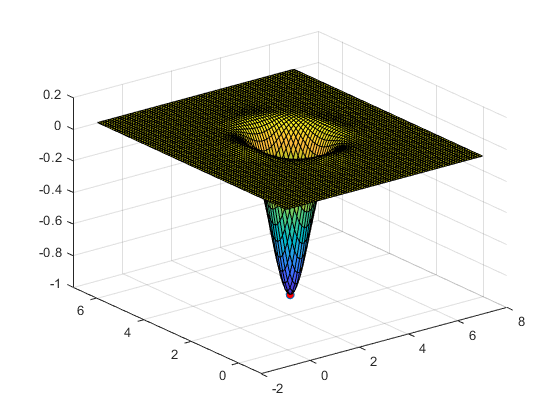

[xx1,xx2] = meshgrid(-1:0.1:7);
zz = ff(xx1,xx2);

surf(xx1,xx2,zz);
hold on;
plot3(xmin2(1),xmin2(2),fmin2,'o','MarkerFaceColor','r');
hold off;

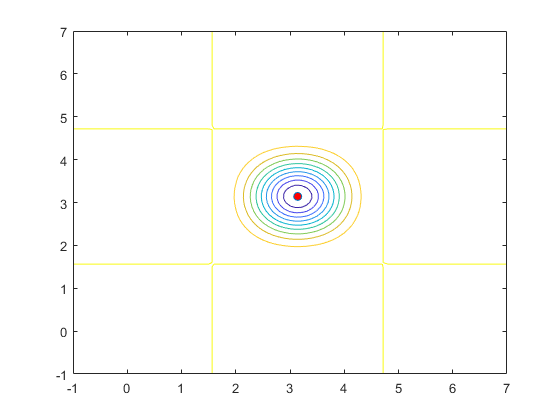

contour(xx1,xx2,zz);
hold on;
plot(xmin2(1),xmin2(2),'o','MarkerFaceColor','r');
hold off;


[xmin_21,fmin_21,flag,output] = fminsearch(@(x) ff(x(1),x(2)),[1 -1])

xmin_21 =     1.3050    1.3050


fmin_21 = -8.1102e-05

flag = 1

output = struct with fields:
    iterations: 48
     funcCount: 93
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


% Not global minimum
[xmin_22,fmin_22,flag,output] = fminsearch(@(x) ff(x(1),x(2)), [4,1])

xmin_22 =     4.9782    1.3050


fmin_22 = -8.1102e-05

flag = 1

output = struct with fields:
    iterations: 38
     funcCount: 72
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


% Not global minimum